# Spinning Model

clear;
clc;
format compact

## Process Model

% Define Process Model Symbol
syms x x_dot y y_dot z_1 z_2 alpha alpha_dot r_1 r_2 T
syms sigma_x sigma_y sigma_z sigma_alpha sigma_r

### State

x_k = [x;
    x_dot;
    y;
    y_dot;
    z_1;
    z_2;
    alpha;
    alpha_dot;
    r_1;
    r_2]

$$x\_k = \left(\begin{array}{c} x\\ \dot{x}\\ y\\ \dot{y}\\ z_{1}\\ z_{2}\\ \alpha \\ \dot{\alpha }\\ r_{1}\\ r_{2} \end{array}\right)$$

#### State Transform Func

f_k = [x + x_dot * T;
    x_dot;
    y + y_dot * T;
    y_dot;
    z_1;
    z_2;
    alpha + alpha_dot * T;
    alpha_dot;
    r_1;
    r_2]

$$f\_k = \left(\begin{array}{c} x+T\,\dot{x}\\ \dot{x}\\ y+T\,\dot{y}\\ \dot{y}\\ z_{1}\\ z_{2}\\ \alpha +T\,\dot{\alpha }\\ \dot{\alpha }\\ r_{1}\\ r_{2} \end{array}\right)$$

### State Jacobian Matrix

F = jacobian(f_k, x_k)

$$F = \left(\begin{array}{cccccccccc} 1 & T & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & T & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1 & T & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

### Process Estimate Covariance Matrix

% DCM
Q = [sigma_x^2*1/3*T^3, sigma_x^2*1/2*T^2, 0,       0,       0,   0,   0,       0,       0,   0;
    sigma_x^2*1/2*T^2, sigma_x^2*T,       0,       0,       0,   0,   0,       0,       0,   0;
    0,       0,        sigma_y^2*1/3*T^3, sigma_y^2*1/2*T^2, 0,   0,   0,       0,       0,   0;
    0,       0,        sigma_y^2*1/2*T^2, sigma_y^2*T,       0,   0,   0,       0,       0,   0;
    0,       0,        0,                 0,       sigma_z^2*T, 0,   0,       0,       0,   0;
    0,       0,        0,                 0,       0,   sigma_z^2*T, 0,       0,       0,   0;
    0,       0,        0,                 0,       0,   0,   sigma_alpha^2*1/3*T^3, sigma_alpha^2*1/2*T^2, 0,   0;
    0,       0,        0,                 0,       0,   0,   sigma_alpha^2*1/2*T^2, sigma_alpha^2*T,       0,   0;
    0,       0,        0,                 0,       0,   0,   0,       0,       sigma_r^2*T, 0;
    0,       0,        0,                 0,       0,   0,   0,       0,       0,   sigma_r^2*T]

$$Q = \begin{array}{l} \left(\begin{array}{cccccccccc} \frac{T^{3}\,{\sigma_{x}}^{2}}{3} & \sigma_{3} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ \sigma_{3} & T\,{\sigma_{x}}^{2} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & \frac{T^{3}\,{\sigma_{y}}^{2}}{3} & \sigma_{2} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & \sigma_{2} & T\,{\sigma_{y}}^{2} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & T\,{\sigma_{z}}^{2} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & T\,{\sigma_{z}}^{2} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & \frac{T^{3}\,{\sigma_{\alpha }}^{2}}{3} & \sigma_{1} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & \sigma_{1} & T\,{\sigma_{\alpha }}^{2} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & T\,{\sigma_{r}}^{2} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & T\,{\sigma_{r}}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{T^{2}\,{\sigma_{\alpha }}^{2}}{2}\\ \sigma_{2}=\frac{T^{2}\,{\sigma_{y}}^{2}}{2}\\ \sigma_{3}=\frac{T^{2}\,{\sigma_{x}}^{2}}{2} \end{array}$$

## Measurement Model

% Define Measurement Model Symbol
syms x_c y_c z_c alpha_m id

### Measurement Matrix

m_k = [x_c, y_c, z_c, alpha_m].'

$$m\_k = \left(\begin{array}{c} x_{c}\\ y_{c}\\ z_{c}\\ \alpha_{m} \end{array}\right)$$

### Measurement Transform Func

% h1
alpha_ = alpha + id * pi/2;
h1_k = [x - r_1 * cos(alpha_);
        y - r_1 * sin(alpha_);
        z_1;
        alpha_]

$$h1\_k = \left(\begin{array}{c} x-r_{1}\,\cos\left(\alpha +\frac{\pi \,\text{id}}{2}\right)\\ y-r_{1}\,\sin\left(\alpha +\frac{\pi \,\text{id}}{2}\right)\\ z_{1}\\ \alpha +\frac{\pi \,\text{id}}{2} \end{array}\right)$$

h2_k = [x - r_2 * cos(alpha_);
        y - r_2 * sin(alpha_);
        z_2;
        alpha_]

$$h2\_k = \left(\begin{array}{c} x-r_{2}\,\cos\left(\alpha +\frac{\pi \,\text{id}}{2}\right)\\ y-r_{2}\,\sin\left(\alpha +\frac{\pi \,\text{id}}{2}\right)\\ z_{2}\\ \alpha +\frac{\pi \,\text{id}}{2} \end{array}\right)$$

### Measurement  Matrix

H_1 = jacobian(h1_k, x_k)

$$H\_1 = \begin{array}{l} \left(\begin{array}{cccccccccc} 1 & 0 & 0 & 0 & 0 & 0 & r_{1}\,\sigma_{1} & 0 & -\sigma_{2} & 0\\ 0 & 0 & 1 & 0 & 0 & 0 & -r_{1}\,\sigma_{2} & 0 & -\sigma_{1} & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\alpha +\frac{\pi \,\text{id}}{2}\right)\\ \sigma_{2}=\cos\left(\alpha +\frac{\pi \,\text{id}}{2}\right) \end{array}$$

H_2 = jacobian(h2_k, x_k)

$$H\_2 = \begin{array}{l} \left(\begin{array}{cccccccccc} 1 & 0 & 0 & 0 & 0 & 0 & r_{2}\,\sigma_{1} & 0 & 0 & -\sigma_{2}\\ 0 & 0 & 1 & 0 & 0 & 0 & -r_{2}\,\sigma_{2} & 0 & 0 & -\sigma_{1}\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\alpha +\frac{\pi \,\text{id}}{2}\right)\\ \sigma_{2}=\cos\left(\alpha +\frac{\pi \,\text{id}}{2}\right) \end{array}$$

### Measurement Estimate Covariance Matrix

由于相机量测模型在球坐标系下定义，所以先进行转换


$$\left(r,\theta ,\phi \right)$$


球坐标往往在直角坐标的基础上定义，三维直角坐标系中的一点 𝑃 的位置可以用 (𝑟,𝜃,𝜙) 这 3 个有序实数来表示，称为该点的**球坐标（spherical coordinates）**。其中 𝑟 表示该点到原点的距离（𝑟⩾0），即位矢的**模长**；𝜃 表示该点的位矢与 𝑧 轴的夹角（𝜃∈[0,𝜋]），即**极角（polar angle）**；𝜙 表示该点的位矢在 𝑥-𝑦 平面上的投影与 𝑥 轴的夹角（𝜙∈[0,2𝜋) 或 (−𝜋,𝜋]），即**方位角（azimuthal angle）**。

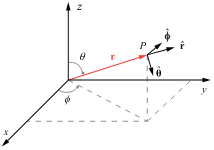   图 1：球坐标系

　　 以上定义的球坐标系符合 [ISO 标准](https://www.iso.org/standard/64973.html)，小时百科统一使用该定义。一些其他文献或软件[**2**](https://wuli.wiki/online/Sph.html#note2)中时常把 𝜃 取补角，即和 𝑥-𝑦 平面的夹角。另一些教材中也可能用 𝜃 表示方位角，𝜙 表示极角，或者将 𝜙 记为 𝜑， 𝑟 记为 𝜌 等，需要通过上下文判断每个坐标符号的具体含义。

syms r theta phi x_c y_c z_c alpha_m sigma_r sigma_theta sigma_phi
x_s = [r;theta;phi]

$$x\_s = \left(\begin{array}{c} r\\ \theta \\ \varphi \end{array}\right)$$


$$Where:
\\
r = \sqrt{x_c^2+ y_c^2 + z_c^2}
\\
\theta = \arctan(\frac{y_c}{x_c})
\\
\phi = atan(\frac{z_c}{x_c})$$


v = [r*sin(theta)*cos(phi);
    r*sin(theta)*sin(phi);
    r*cos(theta)]

$$v = \left(\begin{array}{c} r\,\cos\left(\varphi \right)\,\sin\left(\theta \right)\\ r\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ r\,\cos\left(\theta \right) \end{array}\right)$$

球坐标系到笛卡尔坐标系的Jacobi

V = jacobian(v, x_s)

$$V = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\sin\left(\theta \right) & r\,\cos\left(\varphi \right)\,\cos\left(\theta \right) & -r\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \sin\left(\varphi \right)\,\sin\left(\theta \right) & r\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & r\,\cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right) & -r\,\sin\left(\theta \right) & 0 \end{array}\right)$$

球坐标系下噪声协方差

R_s = diag([sigma_r^2, sigma_theta^2, sigma_phi^2])

$$R\_s = \left(\begin{array}{ccc} {\sigma_{r}}^{2} & 0 & 0\\ 0 & {\sigma_{\theta }}^{2} & 0\\ 0 & 0 & {\sigma_{\varphi }}^{2} \end{array}\right)$$

笛卡尔坐标系下噪声协方差

R_c = V * R_s * V.'

$$R\_c = \begin{array}{l} \left(\begin{array}{ccc} r^{2}\,{\sigma_{\varphi }}^{2}\,{\sin\left(\varphi \right)}^{2}\,{\sin\left(\theta \right)}^{2}+r^{2}\,{\sigma_{\theta }}^{2}\,{\cos\left(\varphi \right)}^{2}\,{\cos\left(\theta \right)}^{2}+{\sigma_{r}}^{2}\,{\cos\left(\varphi \right)}^{2}\,{\sin\left(\theta \right)}^{2} & \sigma_{1} & \sigma_{3}\\ \sigma_{1} & r^{2}\,{\sigma_{\varphi }}^{2}\,{\cos\left(\varphi \right)}^{2}\,{\sin\left(\theta \right)}^{2}+r^{2}\,{\sigma_{\theta }}^{2}\,{\cos\left(\theta \right)}^{2}\,{\sin\left(\varphi \right)}^{2}+{\sigma_{r}}^{2}\,{\sin\left(\varphi \right)}^{2}\,{\sin\left(\theta \right)}^{2} & \sigma_{2}\\ \sigma_{3} & \sigma_{2} & r^{2}\,{\sigma_{\theta }}^{2}\,{\sin\left(\theta \right)}^{2}+{\sigma_{r}}^{2}\,{\cos\left(\theta \right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\cos\left(\varphi \right)\,\sin\left(\varphi \right)\,r^{2}\,{\sigma_{\varphi }}^{2}\,{\sin\left(\theta \right)}^{2}+\cos\left(\varphi \right)\,\sin\left(\varphi \right)\,r^{2}\,{\sigma_{\theta }}^{2}\,{\cos\left(\theta \right)}^{2}+\cos\left(\varphi \right)\,\sin\left(\varphi \right)\,{\sigma_{r}}^{2}\,{\sin\left(\theta \right)}^{2}\\ \sigma_{2}={\sigma_{r}}^{2}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-r^{2}\,{\sigma_{\theta }}^{2}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \sigma_{3}={\sigma_{r}}^{2}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\theta \right)-r^{2}\,{\sigma_{\theta }}^{2}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\theta \right) \end{array}$$

R = [R_c(1,1), R_c(1,2), R_c(1,3), 0;
     R_c(2,1), R_c(2,2), R_c(2,3), 0;
     R_c(3,1), R_c(3,2), R_c(3,3), 0;
     0,     0,     0, 1;]

$$R = \begin{array}{l} \left(\begin{array}{cccc} r^{2}\,{\sigma_{\varphi }}^{2}\,{\sin\left(\varphi \right)}^{2}\,{\sin\left(\theta \right)}^{2}+r^{2}\,{\sigma_{\theta }}^{2}\,{\cos\left(\varphi \right)}^{2}\,{\cos\left(\theta \right)}^{2}+{\sigma_{r}}^{2}\,{\cos\left(\varphi \right)}^{2}\,{\sin\left(\theta \right)}^{2} & \sigma_{1} & \sigma_{3} & 0\\ \sigma_{1} & r^{2}\,{\sigma_{\varphi }}^{2}\,{\cos\left(\varphi \right)}^{2}\,{\sin\left(\theta \right)}^{2}+r^{2}\,{\sigma_{\theta }}^{2}\,{\cos\left(\theta \right)}^{2}\,{\sin\left(\varphi \right)}^{2}+{\sigma_{r}}^{2}\,{\sin\left(\varphi \right)}^{2}\,{\sin\left(\theta \right)}^{2} & \sigma_{2} & 0\\ \sigma_{3} & \sigma_{2} & r^{2}\,{\sigma_{\theta }}^{2}\,{\sin\left(\theta \right)}^{2}+{\sigma_{r}}^{2}\,{\cos\left(\theta \right)}^{2} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\cos\left(\varphi \right)\,\sin\left(\varphi \right)\,r^{2}\,{\sigma_{\varphi }}^{2}\,{\sin\left(\theta \right)}^{2}+\cos\left(\varphi \right)\,\sin\left(\varphi \right)\,r^{2}\,{\sigma_{\theta }}^{2}\,{\cos\left(\theta \right)}^{2}+\cos\left(\varphi \right)\,\sin\left(\varphi \right)\,{\sigma_{r}}^{2}\,{\sin\left(\theta \right)}^{2}\\ \sigma_{2}={\sigma_{r}}^{2}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-r^{2}\,{\sigma_{\theta }}^{2}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \sigma_{3}={\sigma_{r}}^{2}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\theta \right)-r^{2}\,{\sigma_{\theta }}^{2}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\theta \right) \end{array}$$

## 简化模型

syms sigma_x_m
x_s = [x_c;theta;phi]

$$x\_s = \left(\begin{array}{c} x_{c}\\ \theta \\ \varphi \end{array}\right)$$

v = [x_c;
    x_c*tan(theta);
    x_c*tan(phi)]

$$v = \left(\begin{array}{c} x_{c}\\ x_{c}\,\tan\left(\theta \right)\\ x_{c}\,\tan\left(\varphi \right) \end{array}\right)$$


$$Where:
\\
\theta = \arctan(\frac{y_c}{x_c})
\\
\phi = atan(\frac{z_c}{x_c})$$


V = jacobian(v, x_s)

$$V = \left(\begin{array}{ccc} 1 & 0 & 0\\ \tan\left(\theta \right) & x_{c}\,\left({\tan\left(\theta \right)}^{2}+1\right) & 0\\ \tan\left(\varphi \right) & 0 & x_{c}\,\left({\tan\left(\varphi \right)}^{2}+1\right) \end{array}\right)$$

R_s = diag([sigma_x_m^2, sigma_theta^2, sigma_phi^2])

$$R\_s = \left(\begin{array}{ccc} {\sigma_{x,m}}^{2} & 0 & 0\\ 0 & {\sigma_{\theta }}^{2} & 0\\ 0 & 0 & {\sigma_{\varphi }}^{2} \end{array}\right)$$

R_c = V * R_s * V.'

$$R\_c = \begin{array}{l} \left(\begin{array}{ccc} {\sigma_{x,m}}^{2} & \sigma_{2} & \sigma_{3}\\ \sigma_{2} & {\sigma_{x,m}}^{2}\,{\tan\left(\theta \right)}^{2}+{\sigma_{\theta }}^{2}\,{x_{c}}^{2}\,{\left({\tan\left(\theta \right)}^{2}+1\right)}^{2} & \sigma_{1}\\ \sigma_{3} & \sigma_{1} & {\sigma_{x,m}}^{2}\,{\tan\left(\varphi \right)}^{2}+{\sigma_{\varphi }}^{2}\,{x_{c}}^{2}\,{\left({\tan\left(\varphi \right)}^{2}+1\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\sigma_{x,m}}^{2}\,\tan\left(\varphi \right)\,\tan\left(\theta \right)\\ \sigma_{2}={\sigma_{x,m}}^{2}\,\tan\left(\theta \right)\\ \sigma_{3}={\sigma_{x,m}}^{2}\,\tan\left(\varphi \right) \end{array}$$

R = [R_c(1,1), R_c(1,2), R_c(1,3), 0;
     R_c(2,1), R_c(2,2), R_c(2,3), 0;
     R_c(3,1), R_c(3,2), R_c(3,3), 0;
     0,     0,     0, 1;]

$$R = \begin{array}{l} \left(\begin{array}{cccc} {\sigma_{x,m}}^{2} & \sigma_{2} & \sigma_{3} & 0\\ \sigma_{2} & {\sigma_{x,m}}^{2}\,{\tan\left(\theta \right)}^{2}+{\sigma_{\theta }}^{2}\,{x_{c}}^{2}\,{\left({\tan\left(\theta \right)}^{2}+1\right)}^{2} & \sigma_{1} & 0\\ \sigma_{3} & \sigma_{1} & {\sigma_{x,m}}^{2}\,{\tan\left(\varphi \right)}^{2}+{\sigma_{\varphi }}^{2}\,{x_{c}}^{2}\,{\left({\tan\left(\varphi \right)}^{2}+1\right)}^{2} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\sigma_{x,m}}^{2}\,\tan\left(\varphi \right)\,\tan\left(\theta \right)\\ \sigma_{2}={\sigma_{x,m}}^{2}\,\tan\left(\theta \right)\\ \sigma_{3}={\sigma_{x,m}}^{2}\,\tan\left(\varphi \right) \end{array}$$

R = simplify(R)

$$R = \begin{array}{l} \left(\begin{array}{cccc} {\sigma_{x,m}}^{2} & \sigma_{2} & \sigma_{3} & 0\\ \sigma_{2} & {\sigma_{x,m}}^{2}\,{\tan\left(\theta \right)}^{2}+{\sigma_{\theta }}^{2}\,{x_{c}}^{2}\,{\left({\tan\left(\theta \right)}^{2}+1\right)}^{2} & \sigma_{1} & 0\\ \sigma_{3} & \sigma_{1} & {\sigma_{x,m}}^{2}\,{\tan\left(\varphi \right)}^{2}+{\sigma_{\varphi }}^{2}\,{x_{c}}^{2}\,{\left({\tan\left(\varphi \right)}^{2}+1\right)}^{2} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\sigma_{x,m}}^{2}\,\tan\left(\varphi \right)\,\tan\left(\theta \right)\\ \sigma_{2}={\sigma_{x,m}}^{2}\,\tan\left(\theta \right)\\ \sigma_{3}={\sigma_{x,m}}^{2}\,\tan\left(\varphi \right) \end{array}$$